## Importation du fichier CSV

% Lecture du fichier CSV
data = readtable("speed_log1.csv");

% Extraction des colonnes
time_ms = data.time_ms;
V1 = data.V1_rpm;
V2 = data.V2_rpm;
V3 = data.V3_rpm;
V4 = data.V4_rpm;

% Conversion du temps en secondes
time_s = time_ms / 1000;

## Graphique de la vitesse des 4 roues par rapport à la consigne

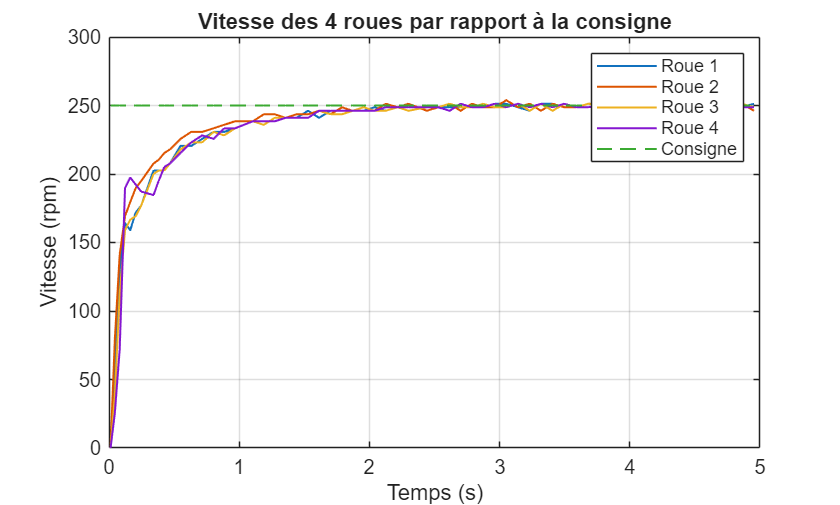

consigne = 250 * ones(size(time_s));

figure
plot(time_s, V1, 'LineWidth', 1)
hold on
plot(time_s, V2, 'LineWidth', 1)
plot(time_s, V3, 'LineWidth', 1)
plot(time_s, V4, 'LineWidth', 1)
plot(time_s, consigne, '--', 'LineWidth', 1)
grid on
xlabel('Temps (s)')
ylabel('Vitesse (rpm)')
title('Vitesse des 4 roues par rapport à la consigne')
legend('Roue 1', 'Roue 2', 'Roue 3', 'Roue 4', 'Consigne')

## Graphique de l'erreur de la vitesse de la roue V1

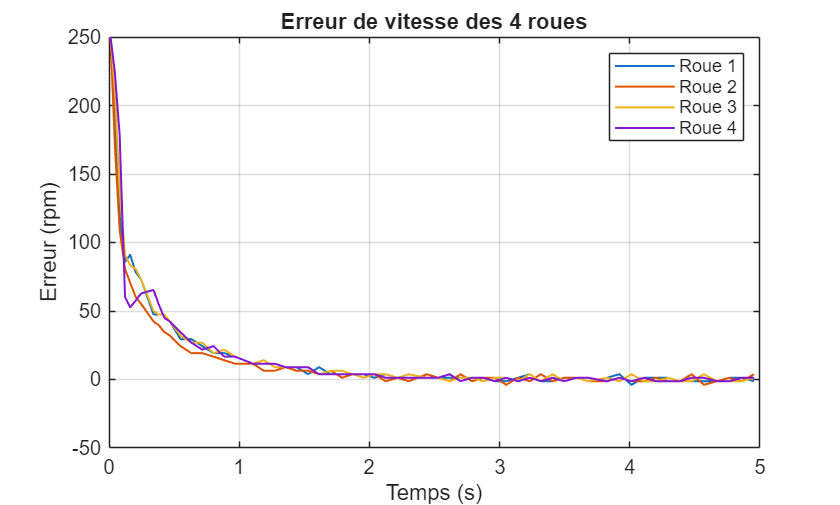

erreurV1 = consigne - V1;
erreurV2 = consigne - V2;
erreurV3 = consigne - V3;
erreurV4 = consigne - V4;

figure
plot(time_s, erreurV1, 'LineWidth', 1)
hold on
plot(time_s, erreurV2, 'LineWidth', 1)
plot(time_s, erreurV3, 'LineWidth', 1)
plot(time_s, erreurV4, 'LineWidth', 1)
grid on
xlabel('Temps (s)')
ylabel('Erreur (rpm)')
title('Erreur de vitesse des 4 roues')
legend('Roue 1', 'Roue 2', 'Roue 3', 'Roue 4')